# What is the Fourier Series

% Housekeeping
close all

## Time and Frequency Vectors

% Sampling Frequency
fs = 1e2;       % 100 Hz

% Sampling time
dT = 1/fs;      % 0.01 s

% Total Time
T = 1;          % 1 s

% Frequency Resolution
df = 1/T;          % 1 Hz

% Time vector
t = 0:dT:T-dT;

% Frequency Vector
f = 0:df:fs-df;

## One sinusoid

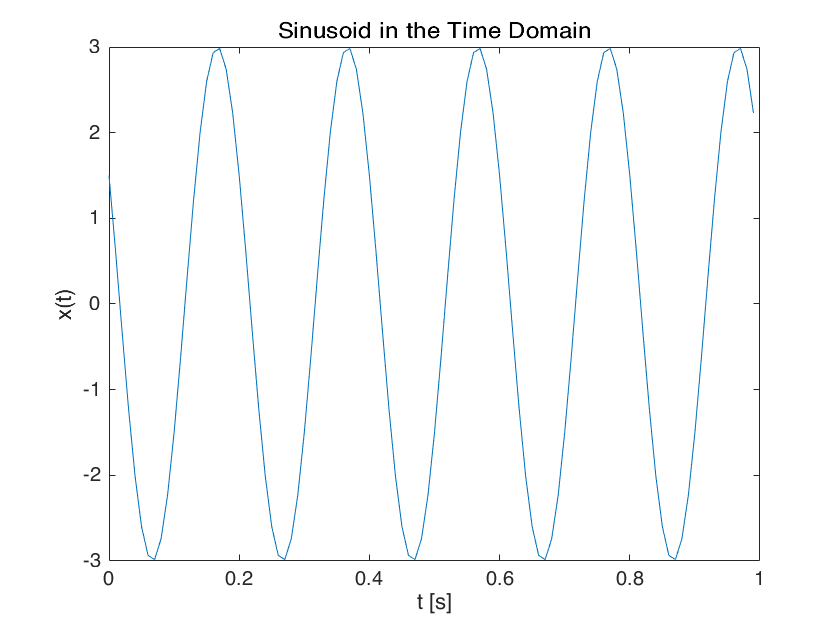

% Amplitude
a = 3;

% Phase
ph=pi/3;

% Radial frequency (corresponding to 5 Hz)
w = 2*pi*5;     % rad/s

% Signal
x = a*cos(w*t+ph);

plot(t,x)
title('Sinusoid in the Time Domain')
xlabel('t [s]')
ylabel('x(t)')

## Fourier Transform

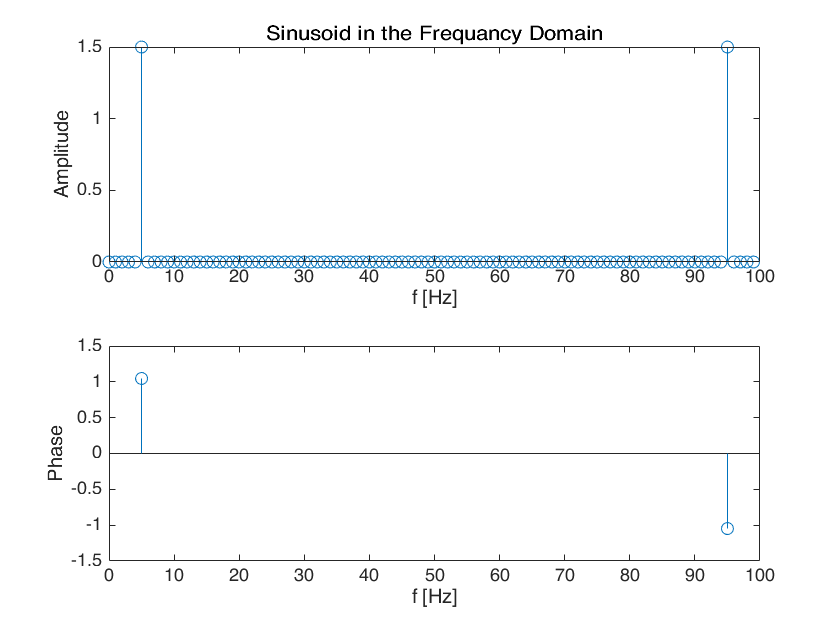

% Fast Fourier Transform
X = fft(x/length(x));

subplot(2,1,1)
stem(f,abs(X))
title('Sinusoid in the Frequancy Domain')
xlabel('f [Hz]')
ylabel('Amplitude')

subplot(2,1,2)
stem(f(abs(X)>1e-12),angle(X(abs(X)>1e-12)))
xlabel('f [Hz]')
ylabel('Phase')

**Note:** here we use logical indexing to plot only the phases that correspond to a non-zero amplitude. This is because if the amplitude is zero the phase is meaningless. 

## Square Wave

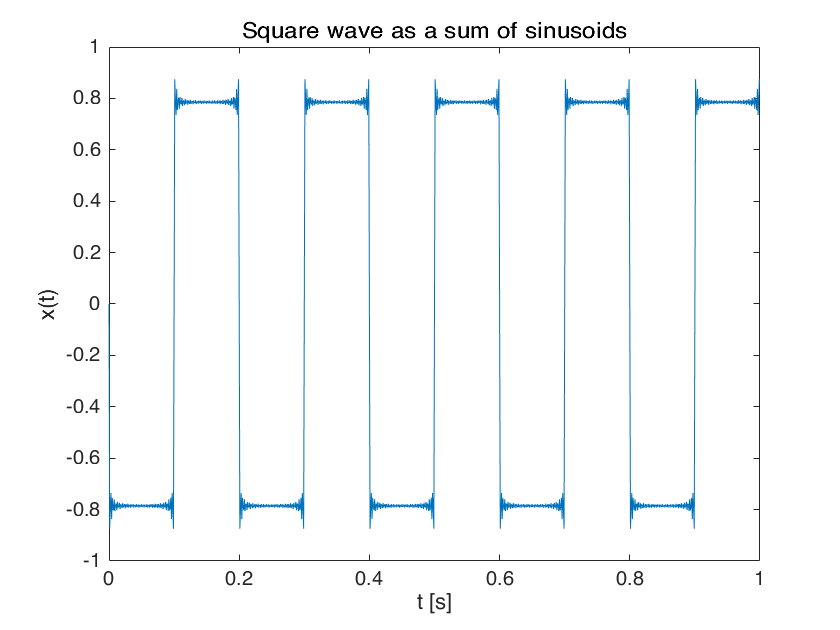

% Sampling Frequency
fs = 1e3;       % 1000 Hz

% Total Time
T = 1;          % 1 s

% Time & Frequencty vectors
t = 0:1/fs:T-1/fs;
f = 0:1/T:fs-1/T;

% Reset x to a vector of 0
x = zeros(size(t));

% New Phase
ph = pi/2;

figure
for w = (1:2:75)*10*pi % Multiples of 5Hz
    
    % Amplitude (Note: it's frequency-dependent!)
    a = 10*pi/w;
    
    % Signal
    x = x + a*cos(w*t+ph);
    
    plot(t,x)
    title('Square wave as a sum of sinusoids')
    xlabel('t [s]')
    ylabel('x(t)')
    
    pause(0.5)
    
end

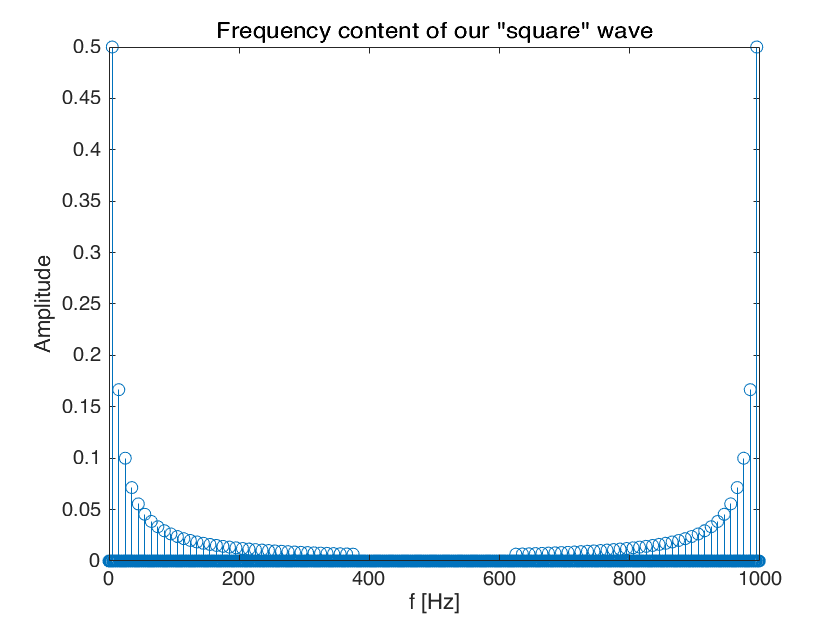


% Frequency vector
f = 0:1/T:fs-1/T;

X = fft(x/length(x));

stem(f,abs(X))
title('Frequency content of our "square" wave')
xlabel('f [Hz]')
ylabel('Amplitude')